# Evaluación 11.1 (Trayectorias en lazo abierto)

Alan Iván Flores Juárez | A01736001

trayectoria ALAN_IVAN                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        

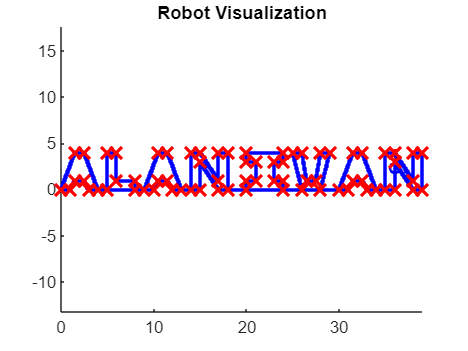

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:390;         % Time array

initPose = [4;0; 3*pi/4];        % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,0; 2.5,4; 1.5,4; 0,0; 1,0; 1.5,1; 2.5,1; 3,0; 4,0; 
    5,0; 8,0; 8,1; 6,1; 6,4; 5,4; 5,0; 8,0;
    9,0; 10.5,4; 11.5,4; 13,0; 12,0; 11.5,1; 10.5,1; 10,0; 9,0; 10.5,4; 11.5,4; 13,0; 14,0; 
    15,0; 15,3; 17,0; 18,0; 18,4; 17,4; 17,1; 15,4; 14,4; 14,0; 15,0; 15,3; 17,0; 18,0; 
    20,0; 24,0; 24,1; 23,1; 23,3; 24,3; 24,4; 20,4; 20,3; 21,3; 21,1; 20,1; 20,0; 24,0;
    26,0; 28,0; 29,4; 28,4; 27.5,1; 26.5,1; 26,4; 25,4; 26,0; 28,0; 30,0; 
    31.5,4; 32.5,4; 34,0; 33,0; 32.5,1; 31.5,1; 31,0; 30,0; 31.5,4; 32.5,4; 34,0; 
    35,0; 36,0; 36,3; 38,0; 39,0; 39,4; 38,4;38,1; 36,4; 35,4; 35,0; 36,0; 36,3; 38,0; 39,0;];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.2;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 8;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

Se eligió el código de landmarks para la realización de esta actividad ya que esta solo requiere de ajustar los valores de velocidad angular y lineal, así como establecer las coordenadas correspondientes a cada letra.

## **Preguntas**

**a) **¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria recta? ¿Porqué?

Los valores que se modifican para ir en línea recta son DesiredLinearVelocity y MaxAngularVelocity, siendo un valor para la primera, en mi caso 0.5 y 0 para la velocidad angular, ya que se busca ir en línea recta.

**b)** ¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria curva? ¿Porqué?

En este caso, se tienen que modificar los valores de velocidad lineal y velocidad angular al mismo tiempo, ya que es necesario que el robot posea de ambos para poder formar una curva y no simplemente un angulo recto.

**c) **¿Cuál fué el o los parámetros que se modifican para obtener un giro? ¿Porqué?

Los parámetros que se modifican es la velocidad angular, dependiendo de la velocidad a la que querramos que de la vuelta, y una velocidad lineal de cero.

**d) **¿Qué papel desempeña el vector del tiempo en la generación de la trayectoria?

El vector de tiempo desempeña el papel de cuanto tiempo se va a ejecutar nuestra simulación, en este caso en segundos, de igual manera este valor se ve afectado por las velocidades establecidas, ya que requerira de más tiempo en caso de que las velocidades sean bajas.

**e) **¿Cuáles fueron los parámetros que se ajustaron para obtener las dimensiones de las trayectorias deseadas?

Los parámetros que se ajustaron fue establecer una velocidad lineal coordial, es decir, ni rápida ni lenta, así como una velocidad angular suficiente para poder formar los ángulos requeridos de la trayectoria, sin olvidar que las coordenadas de cada uno de los vértices de cada letra deben representar de manera correcta la letra deseada.